# Slider Crank Mechanism MBD Simulation

The slider crank mechanism is selected as a simple case study for validating the correctness of the multi-body system dynamics simulation method incorporating the generalized-$\alpha$ method and the FCC-GRB-2D formulation [[1]](https://www.sciencedirect.com/science/article/pii/S0094114X22003809). The parameters of this mechanism is shown in [[2]](https://www.sciencedirect.com/science/article/pii/S0094114X24000119?via%3Dihub).

clear;
clc;
close all; % cleaning

% Parameters of the slider crank mechanism.
numQ = 12; % 3 bodies qi={xi yi uxi uyi} for i=1,2,3.
numCons = 10; % number of constraint equations (full constraint)
M = [0.3,0.087,0.14];
J = [1e-5,4.8037e-4,1e-2]; % the J3 is given as 1e-2 kg*m^2 
L1 = 0.05; % Crank length
L2 = 0.12; % Connecting rod length

% Parameters of the contact model
K = 2.31797e10; % contact stiffness; large stiffness will cause numerical issue!
ce = 0.9; % restitution coefficientQ
muf = 0.02; % friction coefficient
nu0 = 1e-3; % friction tolerance lower
nu1 = 5e-2; % friction tolerance upper
Ri = 10e-3; % bearing radius
Rj = 9.95e-3; % journal radius
Lc = 15e-3; % contact length
Kw = 8e-14; % Archard coefficient
N = 3600; % number of discrete points for bearing contour

% integration parameters
dt = 1e-4; % time step size
NSTEPS = 2e4; % number of total time steps

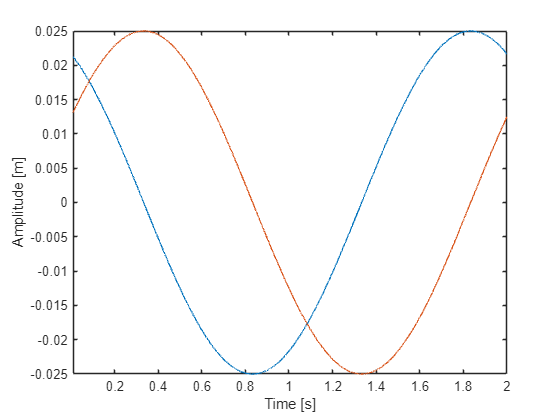

% variable initialization and memory preallocation
Q = nan(numQ,NSTEPS+1);
Qd = nan(numQ,NSTEPS+1);
Qdd = nan(numQ,NSTEPS+1);
Lamda = nan(numCons,NSTEPS+1);

% simulation result is sensitive to the initial values of generalized coordinates!
% initial condition calculation
initAngel = pi/6;
x1_0 = L1/2*cos(initAngel);
y1_0 = L1/2*sin(initAngel);
ux1_0 = 1*cos(initAngel);
uy1_0 = 1*sin(initAngel);
hL1 = L1*cos(initAngel);
vL1 = L1*sin(initAngel);
hL2 = sqrt(L2^2 - vL1^2);
x2_0 = hL1 + hL2/2; 
y2_0 = vL1/2;
ux2_0 = 1*hL2/L2;
uy2_0 = -1*vL1/L2;
x3_0 = hL1 + hL2;
y3_0 = 0;
ux3_0 = 1;
uy3_0 = 0;
q0 = [x1_0,y1_0,ux1_0,uy1_0,x2_0,y2_0,ux2_0,uy2_0,x3_0,y3_0,ux3_0,uy3_0].';
qd0 = phi2QEqns(q0,0)\-phi2tFcn(q0,0);

% qdd0 and lamda0 calculation according to EoM
LHS = [massfcn(q0) phi2QEqns(q0,0).';phi2QEqns(q0,0) zeros(numCons)];
RHS = [genForces(q0,qd0,0);-(phi2qqd2q(q0,qd0,0)*qd0+2*phi2qt(q0,0)*qd0+phi2ttFcn(q0,0))];
Sol = LHS\RHS;
qdd0 = Sol(1:numQ);
lamda0 = Sol(numQ+1:end);


Q(:,1) = q0;
Qd(:,1) = qd0; % qdot initial value
Qdd(:,1) = qdd0; % qddot initial value
% initial lamda is not very sensitive 
Lamda(:,1) = lamda0;
A = Qdd;

bRadius = zeros(1,3600); % bearing contour discretization
impactFlag = false;
deltadotP = 0;


% time step
for n = 1:NSTEPS
    qn = Q(:,n);
    qdn = Qd(:,n);
    qddn = Qdd(:,n);
    an = A(:,n);
    lamdan = Lamda(:,n);
    
    if impactCheck(qn,Ri,Rj,L2)
        % contact condition
        if ~impactFlag
            % free flight to contact event occur
            % \delta^- updating
            deltadotP = getPrevDeltaDot(Q(:,n-1),qn,Qd(:,n-1),qdn,Qdd(:,n-1),qddn,dt,L2,Ri,Rj);
            
            impactFlag = true;
        end

        Qforce = @(q,qd,t) contactQforce(q,qd,K,ce,deltadotP,nu0,nu1,muf,L2,Ri,Rj);
        fcnsCell = {@massfcn,@constEqns,@phi2QEqns,@phi2qt,@phi2tFcn,@phi2ttFcn,@phi2qqd2q,Qforce};
        [Q(:,n+1),Qd(:,n+1),Qdd(:,n+1)] = oneStepRK4Int(qn,qdn,n,dt,fcnsCell);
        
        % ---friction calc---

    else
        % free flight condition
        if impactFlag
            impactFlag=false;
        end

        fcnsCell = {@massfcn,@constEqns,@phi2QEqns,@phi2qt,@phi2tFcn,@phi2ttFcn,@phi2qqd2q,@freeQforce};
        [Q(:,n+1),Qd(:,n+1),Qdd(:,n+1)] = oneStepRK4Int(qn,qdn,n,dt,fcnsCell);

    end
      
end

plot(0:dt:NSTEPS*dt,Q(1:2,:));
xlabel("Time [s]");
ylabel("Amplitude [m]");

### Constraint Equations.

% Construction of constraint equations
function phi = constEqns(q,t)

    % q={q1^T q2^T q3^T}^T where qi={x_i y_i ux_i uy_i}^T
    q1 = q(1:4);
    q2 = q(4+1:4*2);
    q3 = q(4*2+1:3*4);

    % contraint Eqns related to q1
    phi_1 = q1(3:4).'*q1(3:4) - 1;
    phi_2 = consTranMat2D([-.025;0])*q1-[0;0]; % mechanism geo params
    phi_3 = [1;0].'*consTranMat2D([1;0],"vector")*q1 - cos(pi*t+pi/6); % active driver 

    % constraint Eqns related to q2
    phi_4 = q2(3:4).'*q2(3:4) - 1;
    phi_5 = consTranMat2D([.025;0])*q1 - consTranMat2D([-.06;0])*q2; % g
   % phi_6 = consTranMat2D([.06;0])*q2 - consTranMat2D([0;0])*q3; % clearance
   

    % constraint Eqns related to q3
    phi_7 = q3(3:4).'*q3(3:4) - 1;
    phi_8 = q3(2);
    phi_9 = q3(4);

    phi = [phi_1;phi_2;phi_3;phi_4;phi_5;phi_7;phi_8;phi_9]; % phi_6 is discarded
    
end

function phi2q = phi2QEqns(q,~)
    
    % jacobian of constraint equations
    q1 = q(1:4);
    q2 = q(4+1:4*2);
    q3 = q(4*2+1:3*4);

    phi2q = zeros(10,12); % num of DoF equals to constraint equations = 12.
    % fill jacobian matrix with FCC-GRB formulations
    phi2q(1,3:4) = 2*q1(3:4);
    phi2q(2:3,1:4) = consTranMat2D([-.025;0]);
    phi2q(4,1:4) = [1;0].'*consTranMat2D([1;0],"vector");

    phi2q(5,7:8) = 2*q2(3:4);
    phi2q(6:7,1:4) = consTranMat2D([.025;0]);
    phi2q(6:7,5:8) = - consTranMat2D([-.06;0]);
    % phi2q(8:9,5:8) = consTranMat2D([.06;0]);
    % phi2q(8:9,9:end) = - consTranMat2D([0;0]);

    phi2q(8,11:12) = 2*q3(3:4);
    phi2q(9,10) = 1;
    phi2q(10,12) = 1;
    
end

function hybridJac = phi2qqd2q(~,qd,~)
    
    hybridJac = zeros(10,12);
    qd1 = qd(1:4);
    qd2 = qd(4+1:4*2);
    qd3 = qd(4*2+1:4*3);
    hybridJac(1,3:4) = 2*qd1(3:4);
    hybridJac(5,7:8) = 2*qd2(3:4);
    hybridJac(8,11:12) = 2*qd3(3:4);
    
end

function phi2ddt = phi2ttFcn(~,t)
    
    phi2ddt = zeros(10,1);
    phi2ddt(4) = pi^2*cos(pi*t+pi/6);

end

function phi2t = phi2tFcn(~,t)

    phi2t = zeros(10,1);
    phi2t(4) = pi*sin(pi*t+pi/6);
end

function crossJac = phi2qt(~,~)

        crossJac = zeros(10,12);
end

function M = massfcn(~)

    %
    m = [0.3,0.087,0.14]; % mass
    J = [1e-5,4.8037e-4,1e-2]; % moment of inertia
    mJ = [m;J];
    M = kron(diag(mJ(:)),eye(2));
    
end

function Q = genForces(~,~,~)

    % Only gravity
    m = [0.3,0.087,0.14];
    g = 9.8;
    Q = zeros(12,1);
    Q(2:4:12) = -m*g;
end


 

### Clearance revolute joint


function isContact = impactCheck(q,Rb,Rj,L2)
    % clearance joint3 impact detection
    assert(Rb>Rj,"The radius of bearing must be greater than journal!");
    q2 = q(5:8);
    q3 = q(9:end);
    posOB = consTranMat2D([0;0])*q3;
    posOJ = consTranMat2D([L2/2;0])*q2;

    isContact = (vecnorm(posOJ-posOB) - (Rb-Rj)) > 0;

end

function deltaPrev = getPrevDeltaDot(qn,qn1,qdn,qdn1,qddn,qddn1,dt,L2,Rb,Rj)
    % 
    interQ = @(eta) (1-3*eta^2+2*eta^3)*qn + (eta-2*eta^2+eta^3)*dt*qdn + (3*eta^2-2*eta^3)*qn1 + (-eta^2+eta^3)*dt*qdn1;
    interQdot = @(eta) (1-3*eta^2+2*eta^3)*qdn + (eta-2*eta^2+eta^3)*dt*qddn + (3*eta^2-2*eta^3)*qdn1 + (-eta^2+eta^3)*dt*qddn1;
    eta0 = fzero(@interDelta,[0,1]);
    qc = interQ(eta0);
    qdc = interQdot(eta0); % use similar interpolation formular as qc
    posOBc = consTranMat2D([0;0])*qc(9:end); % need geometry parameters
    posOJc = consTranMat2D([L2/2;0])*qc(5:8);
    velOBc = consTranMat2D([0;0])*qdc(9:end);
    velOJc = consTranMat2D([L2/2;0])*qdc(5:8);
    deltaPrev = dot(normalize(posOJc-posOBc,"norm"),velOJc-velOBc);
    
        

    function d = interDelta(x)
            q = interQ(x);
            posOB = consTranMat2D([0;0])*q(9:end);
            posOJ = consTranMat2D([L2/2;0])*q(5:8);
            d = (vecnorm(posOB-posOJ) - (Rb-Rj));
    end
    
end

function [FcJ2B,FcB2J,cPJ,cPB] = getContactForce(q,qd,K,ce,deltaPrev,nu0,nu1,muf,L2,Rb,Rj)


    % Contact Force should be invariant during the time interval n->n+1
    assert(Rb>Rj,"Rb must be greater than Rj!");
    % calc \dot{\delta}
    velBc = consTranMat2D([0;0])*qd(9:end); % The quantities are represented in the GCS.
    velJc = consTranMat2D([L2/2;0])*qd(5:8);
    posBc = consTranMat2D([0;0])*q(9:end);
    posJc = consTranMat2D([L2/2;0])*q(5:8);
    normvec = normalize(posJc-posBc,"norm");
    tangvec = [0 -1;1 0]*normvec;

    delta = vecnorm(posJc-posBc) - (Rb-Rj); % delta will be negative when q and qd is perturbed
    deltadot = dot(normvec,velJc - velBc);
    
    % normal contact force journal to bearing
    Fn = K*max(0,delta)^2*(1+deltadot*3*(1-ce^2)/(4*deltaPrev)); % 
    
    % tangential force calculation
    normdot = (velJc - velBc)/vecnorm(posJc-posBc) - normvec*deltadot/vecnorm(posJc-posBc);
    vt = dot((velJc - velBc)- normdot*(Rb-Rj),tangvec);
    Ft = muf*min(1,max(0,(abs(vt)-nu0)./(nu1-nu0)))*Fn*sign(vt);
    
    FcJ2B = Fn*normvec + Ft*tangvec;
    FcB2J = -FcJ2B;
    cPJ =  [L2/2;0] + [dot(normalize(q(7:8),"norm"),Rj*normvec);dot([0 -1;1 0]*normalize(q(7:8),"norm"),Rj*normvec)]; % local coordinate in journal
    cPB = [dot(normalize(q(11:12),"norm"),Rb*normvec);dot([0 -1;1 0]*normalize(q(11:12),"norm"),Rb*normvec)]; % local coordinate in bearing
end

function contQ = contactQforce(q,qd,K,ce,dP,nu0,nu1,muf,L2,Rb,Rj)
        
        % generalized force vector under contact condition
        [Fcjb,Fcbj,cPj,cPB] = getContactForce(q,qd,K,ce,dP,nu0,nu1,muf,L2,Rb,Rj);
        contQ = zeros(12,1);
        contQ(2:4:12) = -[0.3,0.087,0.14]*9.8; % 
        contQ(5:8) = consTranMat2D(cPj).'*Fcbj; % 局部 -> 全局坐标系
        contQ(9:end) = consTranMat2D(cPB).'*Fcjb;
        
end

function freeQ = freeQforce(~,~,~)
    % only gravity
    m = [0.3,0.087,0.14];
    g = 9.8;
    freeQ = zeros(12,1);
    freeQ(2:4:12) = -m*g;
end


## References

[1] Roupa I, Goncalves S B, da Silva M T. Kinematics and dynamics of planar multibody systems with fully Cartesian coordinates and a generic rigid body[J]. Mechanism and Machine Theory, 2023, 180: 105134.

[2] López-Lombardero M, Cuadrado J, Cabello M, et al. A multibody-dynamics based method for the estimation of wear evolution in the revolute joints of mechanisms that considers link flexibility[J]. Mechanism and Machine Theory, 2024, 194: 105583.